% -------------------------------------------------------------------------
% 4DB00 Dynamics and control of mechanical systems 2020-2021
% CNC challenge.
% -------------------------------------------------------------------------
clc;close all;clearvars
addpath Toolbox
open_system('Toolbox/CNC_Simulink', 'loadonly')

syms xc dxc ddxc yb dyb ddyb phih dphih ddphih

% Define the system parameters, actuator force and time
% as symbolic expressions
syms g Lf Lb L23 L24 wc hc mf mb mc mh Jh2 kPD dPD dx kphi dphi xref phiref phih3
syms Mphi
syms t
syms func

% Place degrees of freedom (and their derivatives) in the generalized
% coordinates and the prescribed displacements.
Components.q        = [xc;phih];
Components.dq       = [dxc;dphih];
Components.ddq      = [ddxc;ddphih];
Components.s_pd     = [yb];
Components.ds_pd    = [dyb];
Components.dds_pd   = [ddyb];
Components.F        = [Mphi];
Components.time     = [t];

% Define system parameters as symbols
Components.parameters.g.symbol  = g;
Components.parameters.Lf.symbol = Lf;
Components.parameters.Lb.symbol = Lb;
Components.parameters.L23.symbol = L23;
Components.parameters.L24.symbol = L24;
Components.parameters.wc.symbol = wc;
Components.parameters.hc.symbol = hc;
Components.parameters.mf.symbol = mf;
Components.parameters.mb.symbol = mb;
Components.parameters.mc.symbol = mc;
Components.parameters.mh.symbol = mh;
Components.parameters.Jh2.symbol = Jh2;
Components.parameters.kPD.symbol = kPD;
Components.parameters.dPD.symbol = dPD;
Components.parameters.dx.symbol = dx;
Components.parameters.kphi.symbol = kphi;
Components.parameters.dphi.symbol = dphi;
Components.parameters.xref.symbol = xref;
Components.parameters.phiref.symbol = phiref;
Components.parameters.phih3.symbol = phih3;


% Insert the system parameter values:
Components.parameters.g.value      = [9.81]; %m/(s^2)   (gravity acceleration)
Components.parameters.Lf.value     = [1]; %m            (Length of the vertical frames)
Components.parameters.Lb.value     = [0.8]; %m          (Length of the horizontal beam)
Components.parameters.L23.value    = [0.05]; %m         (Distance between points 2 and 3)
Components.parameters.L24.value    = [0.1]; %m          (Distance between points 2 and 4)
Components.parameters.wc.value     = [0.1]; %m          (Width of the carraige)
Components.parameters.hc.value     = [0.08]; %m         (Height of the carriage)
Components.parameters.mf.value     = [10]; %kg          (Mass of the frame)
Components.parameters.mb.value     = [10]; %kg          (Mass of the beam)
Components.parameters.mc.value     = [1.5]; %kg         (Mass of the carriage)
Components.parameters.mh.value     = [0.5]; %kg         (Mass of the milling head)
Components.parameters.Jh2.value    = [0.5]; %kg*m^2     (Rotational ineratia of the milling head)
Components.parameters.kPD.value    = [350]; %N/m        (PD controller P gain)
Components.parameters.dPD.value    = [10]; %N*s/(m)     (PD controller D gain)
Components.parameters.dx.value     = [0.5]; %N*s/(m)    (Damping coefficient of the carraige)
Components.parameters.kphi.value   = [500]; %N*m/rad    (Spring coefficient of the band brake)
Components.parameters.dphi.value   = [2]; %N*m*s/rad    (Damping coefficient of the band brake)
Components.parameters.xref.value   = [0.5]; %m          (Reference position of carraige)
Components.parameters.phiref.value = [-pi/2]; %rad      (Reference angle of band brake)
Components.parameters.phih3.value  = [-2*pi/3]; %rad    (Relative angles of mass mh)


% Insert symbolic expressions for the kinetic and potential energy
% and the generalized forces:
T   = [0.5*Jh2*dphih^2+0.5*mb*dyb^2+0.5*mc*(dxc^2+dyb^2)+0.5*mh*(dxc^2+dyb^2)+mh*L23*dphih*(-dxc*sin(phih+phih3)+dyb*cos(phih+phih3))] %Given Kinetic energy

$$T = \frac{{\mathrm{Jh}}_{2}\,{\mathrm{dphih}}^{2}}{2}+\frac{{\mathrm{dyb}}^{2}\,\mathrm{mb}}{2}+\frac{\mathrm{mc}\,\left({\mathrm{dxc}}^{2}+{\mathrm{dyb}}^{2}\right)}{2}+\frac{\mathrm{mh}\,\left({\mathrm{dxc}}^{2}+{\mathrm{dyb}}^{2}\right)}{2}+L_{23}\,\mathrm{dphih}\,\mathrm{mh}\,\left(\mathrm{dyb}\,\cos\left(\mathrm{phih}+{\mathrm{phih}}_{3}\right)-\mathrm{dxc}\,\sin\left(\mathrm{phih}+{\mathrm{phih}}_{3}\right)\right)$$

%T   = [0.5*dyb^2*(mb+mc+mh)+0.5*dxc^2*(mc+mh)+0.5*dphih^2*(Jh2+mh*L23^2)-mh*dphih*L23*(dxc*sin(phih3+phih)+dyb*cos(phih3+phih))]   %Non-Given Kinetic energy
V   = [mf*g*Lf+(mb+mc)*g*yb+mh*g*(yb+L23*sin(phih+phih3))+0.5*kPD*(xc-xref)^2+0.5*kphi*(phih-phiref)^2]   % Given Potential energy

$$V = \frac{\mathrm{kphi}\,{\left(\mathrm{phih}-\mathrm{phiref}\right)}^{2}}{2}+\frac{\mathrm{kPD}\,{\left(\mathrm{xc}-\mathrm{xref}\right)}^{2}}{2}+g\,\mathrm{mh}\,\left(\mathrm{yb}+L_{23}\,\sin\left(\mathrm{phih}+{\mathrm{phih}}_{3}\right)\right)+g\,\mathrm{yb}\,\left(\mathrm{mb}+\mathrm{mc}\right)+\mathrm{Lf}\,g\,\mathrm{mf}$$

%V   = [g*((mb+mc+mh)*(yb)-L23*mh*sin(phih3+phih))+ 0.5*kphi*(phih-phiref)^2+0.5*kPD*(xc-xref)^2]  %Non-Given Potential energy
Qnc = [-(dPD+dx)*dxc;Mphi-dphi*dphih]   %Given Generalised forces

$$Qnc = \left(\begin{array}{c} -\mathrm{dxc}\,\left(\mathrm{dPD}+\mathrm{dx}\right)\\ \mathrm{Mphi}-\mathrm{dphi}\,\mathrm{dphih} \end{array}\right)$$

%Qnc = [-(dPD+dx)*dxc;-dphi*dphih] %Non-Given Generalised forces


# Deliverable 3

## 3.a

**Setting the damping coefficients to zero**

Components.parameters.dPD.value    = [0]; %N*s/(m)     (PD controller D gain)
Components.parameters.dx.value     = [0]; %N*s/(m)    (Damping coefficient of the carraige)
Components.parameters.dphi.value   = [0]; %N*m*s/rad    (Damping coefficient of the band brake)

**Calculating the Linear model**

%Calculating the non linear EOM
Nonlinear_EOM_undamped = DOMS('NonlinearEOM',Components,T,V,Qnc);

q_0_stable = [0.5; -1.570];

LinearEOM_undamped = DOMS('Linearize',Components,Nonlinear_EOM_undamped,q_0_stable);
LinearEOM_undamped.D %matrix D must be zeros

ans =      0     0
     0     0


**Calculating eigenfreqiencies **

[U, lambda] = eig(LinearEOM_undamped.K, LinearEOM_undamped.M);
w = sqrt(lambda);
w1 = w(1,1)

w1 = 13.2285

w2 = w(2,2)

w2 = 31.6219

u1 = U(:,1)

u1 =    -0.7071
    0.0037


u2 = U(:,2)

u2 =     0.0107
    1.4143


**Simulating the eigenfreqencies to check for proper response**

Components.parameters.dPD.value    = [0]; %N*s/(m)     (PD controller D gain)
Components.parameters.dx.value     = [0]; %N*s/(m)    (Damping coefficient of the carraige)
Components.parameters.dphi.value   = [0]; %N*m*s/rad    (Damping coefficient of the band brake)
% Simulating the eigenfrequency response to check for proper behavior
t_sim = [10];
q_init = q_0_stable;
dq_init = [0;0];
s_pd_of_t = [0];
M_of_t    = [20*sin(w2*t)];

Sim_Setup_a  = DOMS('Sim_Setup',Components,t_sim,...
    q_init,dq_init,s_pd_of_t, M_of_t);

**Plotting figures**

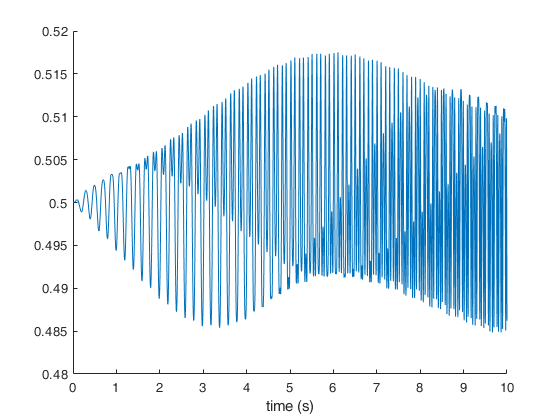

figure(1)
clf;    %clearing the figure
hold on;

plot(Sim_Setup_a.t,Sim_Setup_a.qt(:,1)) %plotting data

%ylabel("xc (m)") 
xlabel("time (s)")

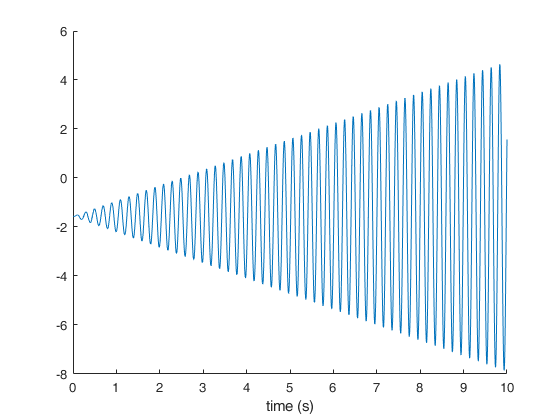

figure(2)
clf;    %clearing the figure
hold on;

plot(Sim_Setup_a.t,Sim_Setup_a.qt(:,2)) %plotting data

%ylabel("xc (m)") 
xlabel("time (s)")

## 3.b

[https://nl.mathworks.com/help/matlab/ref/eig.html](https://nl.mathworks.com/help/matlab/ref/eig.html)

" The eigenvectors in U are normalized so that the 2-norm of each is 1"

Mass matrix normalization

## **3.c**

**Setting paramaters to zero**

Components.parameters.dPD.value    = [0]; %N*s/(m)     (PD controller D gain)
Components.parameters.dx.value     = [0]; %N*s/(m)    (Damping coefficient of the carraige)
Components.parameters.dphi.value   = [0]; %N*m*s/rad    (Damping coefficient of the band brake)

**Setting desired parameters**

t_sim = [10];

q_0_1 = 0.003*u1;
q_0_2 = 0.1*u2;
q_0_3 = [0; 0.12];
q_0_4 = [0.002; 0.06];

dq_init = [0;0];
s_pd_of_t = [0];
M_of_t    = [0];  


**Calculating the linear models around desired starting positions**

q_init = q_0_1;
Sim_Linear_1 = DOMS('Sim_Linear',Components,LinearEOM_undamped,...
    t_sim,q_init,dq_init,s_pd_of_t, M_of_t);

q_init = q_0_2;
Sim_Linear_2 = DOMS('Sim_Linear',Components,LinearEOM_undamped,...
    t_sim,q_init,dq_init,s_pd_of_t, M_of_t);

q_init = q_0_3;
Sim_Linear_3 = DOMS('Sim_Linear',Components,LinearEOM_undamped,...
    t_sim,q_init,dq_init,s_pd_of_t, M_of_t);

q_init = q_0_4;
Sim_Linear_4 = DOMS('Sim_Linear',Components,LinearEOM_undamped,...
    t_sim,q_init,dq_init,s_pd_of_t, M_of_t);

**Plotting the figure**

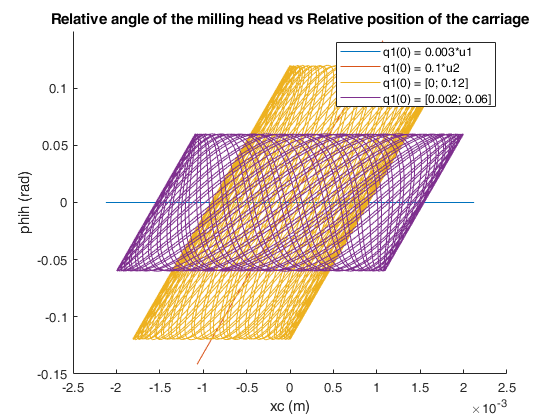

figure(3)
clf;    %clearing the figure
hold on;

plot(Sim_Linear_1.q1t(:,1),Sim_Linear_1.q1t(:,2)) 
plot(Sim_Linear_2.q1t(:,1),Sim_Linear_2.q1t(:,2)) 
plot(Sim_Linear_3.q1t(:,1),Sim_Linear_3.q1t(:,2)) 
plot(Sim_Linear_4.q1t(:,1),Sim_Linear_4.q1t(:,2)) 

legend("q1(0) = 0.003*u1","q1(0) = 0.1*u2", "q1(0) = [0; 0.12]","q1(0) = [0.002; 0.06]") % setting legend
title("Relative angle of the milling head vs Relative position of the carriage") 
ylabel("phih (rad)") 
xlabel("xc (m)")
xlim([-0.0025 0.0025])
ylim([-0.15 0.15])

## 3.d

For each time trajectory, explain whether or not the eigenvectors u1 and u2 are visible in the corresponding response of the system. If so, what do you observe?

u1 only effects the x position of the carriage and the relative angle of the milling head stays consistent

u2 effects both the relative position of the carriage and the relative angle of the milling head, but it does this in a linear way

## 3.e

**Setting desired damping values**

Components.parameters.dPD.value    = [10]; %N*s/(m)     (PD controller D gain)
Components.parameters.dx.value     = [0.5]; %N*s/(m)    (Damping coefficient of the carraige)
Components.parameters.dphi.value   = [2]; %N*m*s/rad    (Damping coefficient of the band brake)

**Setting desired simulation variables**

t_sim = [5];
q_init = [0.5; -0.5*pi];
dq_init = [0; 0];
s_pd_of_t = 0.5;
M_of_t = [30*sin(w2*t)];

**Checking the if the variables are properly set**

Nonlinear_EOM_damped = DOMS('NonlinearEOM',Components,T,V,Qnc);
LinearEOM_damped = DOMS('Linearize',Components,Nonlinear_EOM_damped,q_0_stable);
LinearEOM_damped.D %if matrix D is non zeros the setup is correct

ans =    10.5000         0
         0    2.0000


**Performing the simulation**

Sim_Setup_e  = DOMS('Sim_Setup',Components,t_sim,...
    q_init,dq_init,s_pd_of_t, M_of_t);

**Plotting the figures**

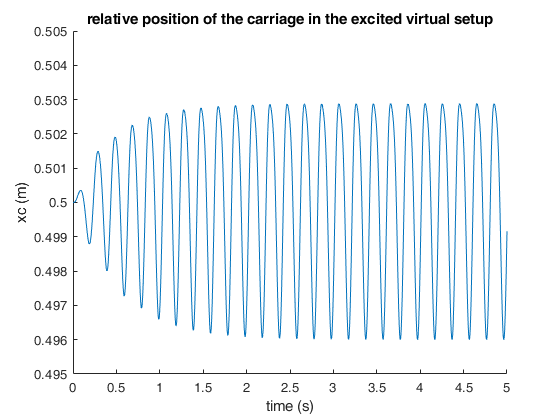

figure(4)
clf;    %clearing the figure
hold on;

plot(Sim_Setup_e.t,Sim_Setup_e.qt(:,1)) %plotting data

title("relative position of the carriage in the excited virtual setup")
ylabel("xc (m)") 
xlabel("time (s)")
xlim([0 5])
ylim([0.495 0.505])

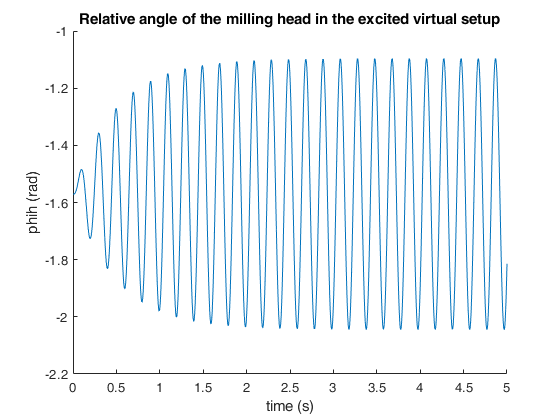

figure(5)
clf;    %clearing the figure
hold on;

plot(Sim_Setup_e.t,Sim_Setup_e.qt(:,2)) %plotting data

title("Relative angle of the milling head in the excited virtual setup")
ylabel("phih (rad)") 
xlabel("time (s)")
xlim([0 5])
ylim([-2.2 -1])

## 3.f

### W = 0.8

**Setting desired damping values**

Components.parameters.dPD.value    = [10]; %N*s/(m)     (PD controller D gain)
Components.parameters.dx.value     = [0.5]; %N*s/(m)    (Damping coefficient of the carraige)
Components.parameters.dphi.value   = [2]; %N*m*s/rad    (Damping coefficient of the band brake)

**Setting desired simulation variables**

W = 0.9;

t_sim = [5];
q_init = [0.5; -0.5*pi];
dq_init = [0; 0];
s_pd_of_t = 0.5;
M_of_t = [30*sin(W*w2*t)];

**Performing the simulation**

Sim_Setup_f1  = DOMS('Sim_Setup',Components,t_sim,...
    q_init,dq_init,s_pd_of_t, M_of_t);

**Plotting the figures**

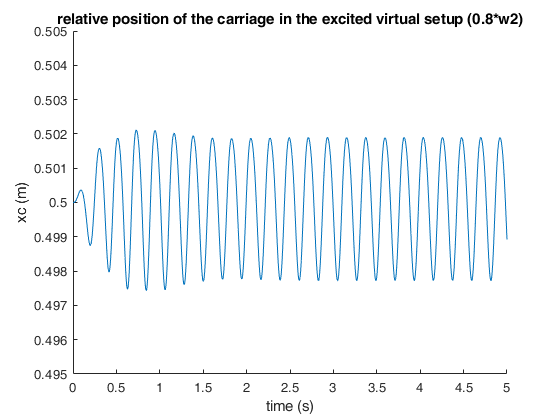

figure(6)
clf;    %clearing the figure
hold on;

plot(Sim_Setup_f1.t,Sim_Setup_f1.qt(:,1)) %plotting data

title("relative position of the carriage in the excited virtual setup (0.8*w2)")
ylabel("xc (m)") 
xlabel("time (s)")
xlim([0 5])
ylim([0.495 0.505])

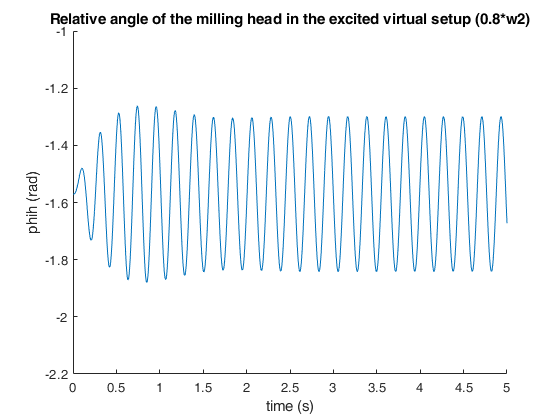

figure(7)
clf;    %clearing the figure
hold on;

plot(Sim_Setup_f1.t,Sim_Setup_f1.qt(:,2)) %plotting data

title("Relative angle of the milling head in the excited virtual setup (0.8*w2)")
ylabel("phih (rad)") 
xlabel("time (s)")
xlim([0 5])
ylim([-2.2 -1])

### W = 1.2

**Setting desired damping values**

Components.parameters.dPD.value    = [10]; %N*s/(m)     (PD controller D gain)
Components.parameters.dx.value     = [0.5]; %N*s/(m)    (Damping coefficient of the carraige)
Components.parameters.dphi.value   = [2]; %N*m*s/rad    (Damping coefficient of the band brake)

**Setting desired simulation variables**

w = 1.2;

t_sim = [5];
q_init = [0.5; -0.5*pi];
dq_init = [0; 0];
s_pd_of_t = 0.5;
M_of_t = [30*sin(W*w2*t)];

**Performing the simulation**

Sim_Setup_f2  = DOMS('Sim_Setup',Components,t_sim,...
    q_init,dq_init,s_pd_of_t, M_of_t);

**Plotting the figures**

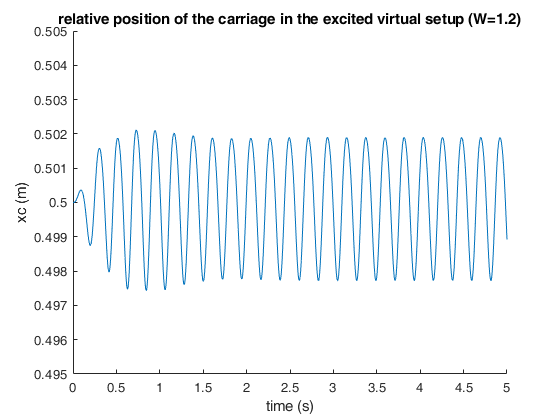

figure(6)
clf;    %clearing the figure
hold on;

plot(Sim_Setup_f2.t,Sim_Setup_f2.qt(:,1)) %plotting data

title("relative position of the carriage in the excited virtual setup (W=1.2)")
ylabel("xc (m)") 
xlabel("time (s)")
xlim([0 5])
ylim([0.495 0.505])

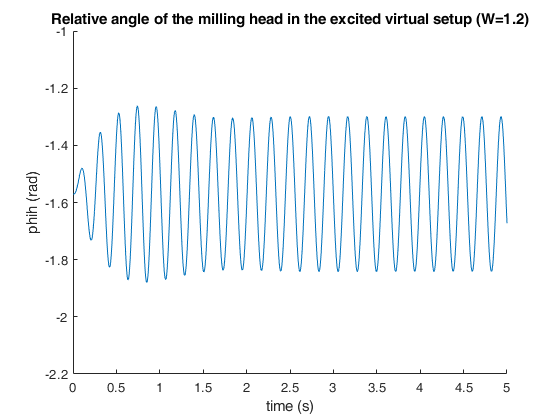

figure(7)
clf;    %clearing the figure
hold on;

plot(Sim_Setup_f2.t,Sim_Setup_f2.qt(:,2)) %plotting data

%legend("Simulink simulation","Non Linear equation of motion simulation") % setting legend
title("Relative angle of the milling head in the excited virtual setup (W=1.2)")
ylabel("phih (rad)") 
xlabel("time (s)")
xlim([0 5])
ylim([-2.2 -1])

The aplification is much less when you are not close to the break frequency

## 3.g

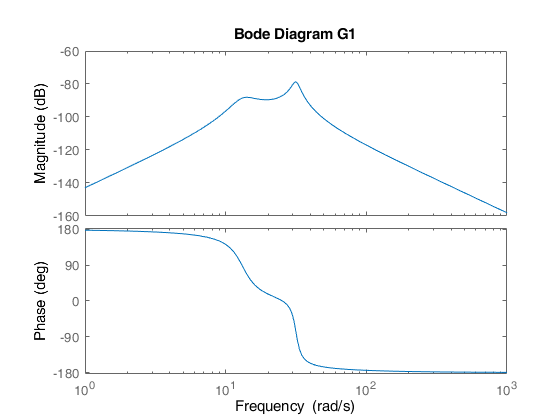

TF = DOMS("Make_tf",LinearEOM_damped);
G1 =TF(1);
G2 = TF(2);
figure(8)
bode(G1)
title("Bode Diagram G1")

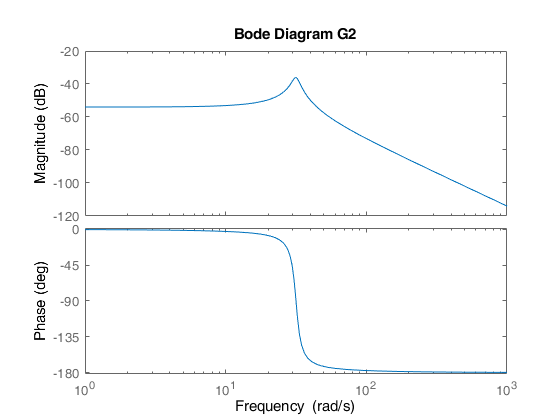

figure(9)
bode(G2)
title("Bode Diagram G2")

## 3.h

G1

G1 =
 
      0.01248 s^2 + 1.109e-17 s - 3.982e-15
  ---------------------------------------------
  s^4 + 9.251 s^3 + 1196 s^2 + 5950 s + 1.75e05
 
Continuous-time transfer function.



G2

G2 =
 
             2 s^2 + 10.5 s + 350.1
  ---------------------------------------------
  s^4 + 9.251 s^3 + 1196 s^2 + 5950 s + 1.75e05
 
Continuous-time transfer function.



[Z1,gain1] = zero(G1)

Z1 = 	1.0e+-6 *

   -0.5648
    0.5648


gain1 = 0.0125

[Z2,gain2] = zero(G2)

Z2 =   -2.6250 +12.9657i
  -2.6250 -12.9657i


gain2 = 2.0003

# Deliverable 4

dq_impulse = inv(LinearEOM_damped.M) * LinearEOM_damped.Q

dq_impulse =     0.0125
    2.0003


G1-G2 %Total transfer function

ans =
 
             -1.988 s^6 - 28.89 s^5 - 2825 s^4 - 2.762e04 s^3 - 8.29e05 s^2 - 3.92e06 s - 6.125e07
  ------------------------------------------------------------------------------------------------------------
  s^8 + 18.5 s^7 + 2477 s^6 + 3.403e04 s^5 + 1.89e06 s^4 + 1.747e07 s^3 + 4.539e08 s^2 + 2.082e09 s + 3.062e10
 
Continuous-time transfer function.



G_mil = minreal(G1-G2) %non contributing factors are removed

G_mil =
 
               -1.988 s^4 - 20.94 s^3 - 753 s^2 - 3675 s - 6.126e04
  ------------------------------------------------------------------------------
  s^6 + 14.5 s^5 + 1420 s^4 + 1.385e04 s^3 + 4.155e05 s^2 + 1.96e06 s + 3.062e07
 
Continuous-time transfer function.



## 4.a

pole(G2)

ans =   -2.0009 +31.5584i
  -2.0009 -31.5584i
  -2.6248 +12.9655i
  -2.6248 -12.9655i


## 4.b

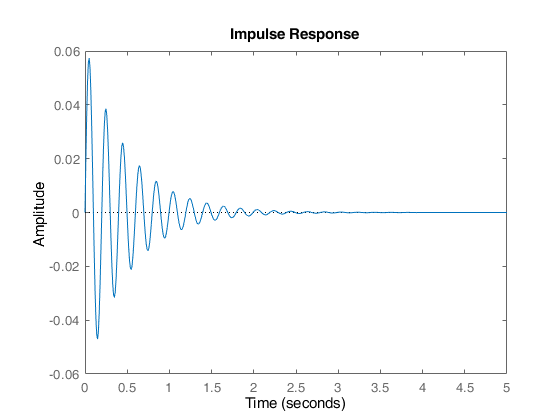


impulse(G2,5)

%ylim([-1.63 -1.51])

## 4.c

**Setting desired damping values**

Components.parameters.dPD.value    = [10]; %N*s/(m)     (PD controller D gain)
Components.parameters.dx.value     = [0.5]; %N*s/(m)    (Damping coefficient of the carraige)
Components.parameters.dphi.value   = [2]; %N*m*s/rad    (Damping coefficient of the band brake)

**Setting desired simulation variables**

t_sim = [5];
q_init = [0.5; -0.5*pi];
dq_init = dq_impulse;
s_pd_of_t = 0;
M_of_t = [0];

**Performing the simulation**

Sim_Setup_4c  = DOMS('Sim_Setup',Components,t_sim,...
    q_init,dq_init,s_pd_of_t, M_of_t);

**Plotting the figures**

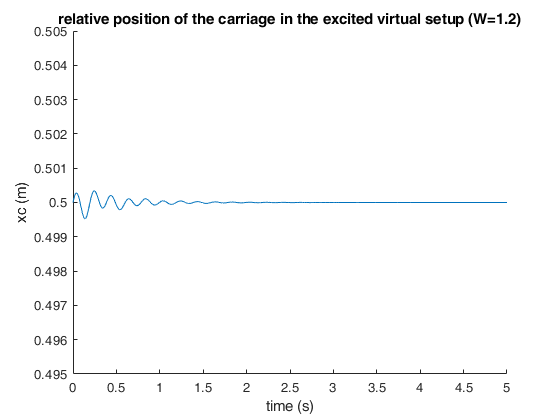

figure(10)
clf;    %clearing the figure
hold on;

plot(Sim_Setup_4c.t,Sim_Setup_4c.qt(:,1)) %plotting data

%legend("Simulink simulation","Non Linear equation of motion simulation") % setting legend
title("relative position of the carriage in the excited virtual setup (W=1.2)")
ylabel("xc (m)") 
xlabel("time (s)")
xlim([0 5])
ylim([0.495 0.505])

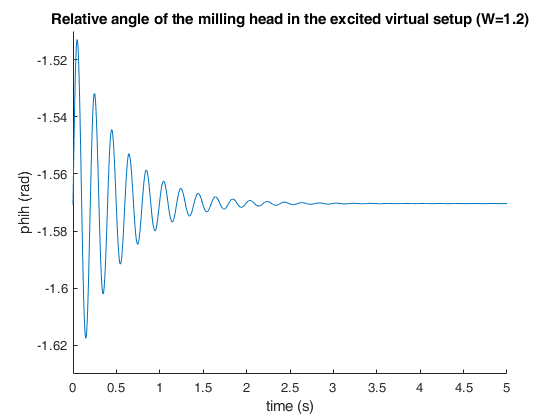

figure(10)
clf;    %clearing the figure
hold on;

plot(Sim_Setup_4c.t,Sim_Setup_4c.qt(:,2)) %plotting data

%legend("Simulink simulation","Non Linear equation of motion simulation") % setting legend
title("Relative angle of the milling head in the excited virtual setup (W=1.2)")
ylabel("phih (rad)") 
xlabel("time (s)")
xlim([0 5])
ylim([-1.63 -1.51])

## 4.d

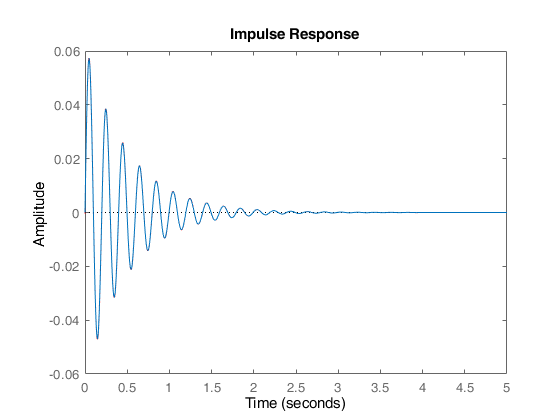

figure()
clf;
hold on;

plot(Sim_Setup_4c.t,Sim_Setup_4c.qt(:,2)+1.57037,"r")
impulse(G2,5)

## 4.e

Is the closed loop transfer functions between input r and output y stable?

rh(t) is the desired orientation

e(t) = phih(t)-rh(t);   

Controller is described by:            C(s) = 100

CNC machine is described by:     G2(s)

C = 100;
T_cl = minreal((G2*C)/(1+G2*C)) % creating the transfer function of the closed loop system

T_cl =
 
          200 s^2 + 1050 s + 3.501e04
  --------------------------------------------
  s^4 + 9.251 s^3 + 1396 s^2 + 7000 s + 2.1e05
 
Continuous-time transfer function.



pole(T_cl)

ans =   -2.0009 +34.5827i
  -2.0009 -34.5827i
  -2.6249 +12.9656i
  -2.6249 -12.9656i


## 4.f

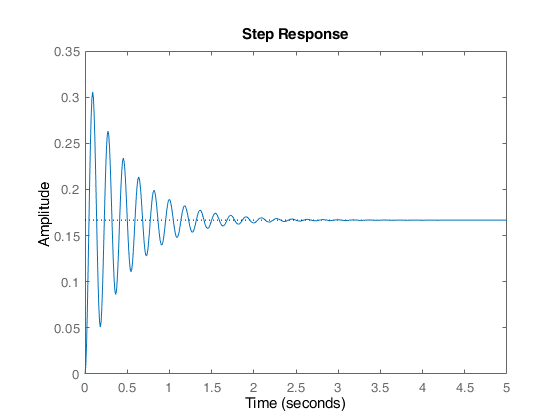

figure()
clf;
step(T_cl,5)

## 4.g

**Setting parameters**

t_sim = 5;
q_init = q_0_stable;
dq_init = [0; 0];
s_pd_of_t = 0.5;
ref_signal = "Step";
ref_settings = [-1.57 -0.57 0];

**Doing the simulations**

C = 100; %setting controller value

Unrecognized function or variable 's'.

Sim_step1 = DOMS("Sim_Control",Components, t_sim, q_init, dq_init, s_pd_of_t, C, ref_signal, ref_settings);

C = 1000; %setting controller value
Sim_step2 = DOMS("Sim_Control",Components, t_sim, q_init, dq_init, s_pd_of_t, C, ref_signal, ref_settings);

C = 10000; %setting controller value
Sim_step3 = DOMS("Sim_Control",Components, t_sim, q_init, dq_init, s_pd_of_t, C, ref_signal, ref_settings);

**Plotting the figure**

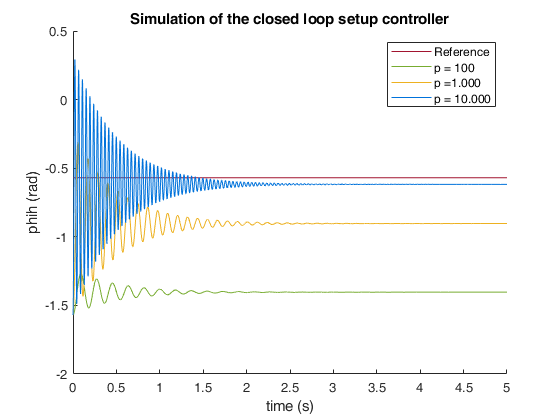


figure(10)
clf;    
hold on;
plot([0;5], [-0.57;-0.57],"Color","#A2142F");
plot(Sim_step1.t,Sim_step1.qt(:,2),"Color","#77AC30")
plot(Sim_step2.t,Sim_step2.qt(:,2),"Color","#EDB120")
plot(Sim_step2.t,Sim_step3.qt(:,2),"Color","#0072DB")

legend("Reference","p = 100","p =1.000","p = 10.000")
title("Simulation of the closed loop setup controller")
ylabel("phih (rad)") 
xlabel("time (s)")
xlim([0 5])
ylim([-2 0.5])

## 4.h

What is the effect of increasing and decreasing the gain P in question g?

## 4.i

Based on your findings in this deliverable, would you recommend the use of a proportional controller C(s) = P for this application?